# Post-processing Analysis of the Social Foraging Experiment

## Load the data

% Load the table of rec info
ParDir = 'Z:\users\Tatsumi\data\MultiReward'; % parent directory
recListPath = 'G:\My Drive\YartsevLab\Experiment\Multi_reward\Log\Multireward_exp_list_2024.xlsx'; % table of rec info
allRecs = GetRecList(recListPath); % load the rec info list

Show the list of all recordings for this experiment cycle.

disp(allRecs)

       date             place           recName                          rootdir                         expType      rewardType      reward_list          s1             s2             s3             s4         14447    11827    29924    14406    14561    14633    14662    14531    71050    9776           ephysDir             ephysBat     probeNum        trjName        hemisphere       recType        len_min      merge         upload       extract       kilosor

Then load the data from one of the recording file in the list. The session to be loaded is specified by the row number in the table.

The data types that have to be loaded are specified by a series of symbols corresponding to each data type. For example, 'abs' is given as *dataTypes* in the *loadExpData* function to load the analog signals, extracted behavioral features, and spike data. The order of the output variables is the same as the order of the input symbols, so the first output variable is the analog signals and the second one is the behavioral data in this example.

% Specify the index of session to be loaded
recID = 6; 

% select the figures to output
opts.flight_cluster = true;
opts.feeder_preference = true;
opts.reward_preference = true;
opts.lfp_corr = true;
opts.spike_raster = true;
opts.SU_waveform = true;
opts.SU_raster_uncluster = true;
opts.SU_raster_cluster = true;
opts.SU_raster_reward = true;
opts.SU_raster_recurrent = true;
opts.SU_raster_social = true;

% general information
expType = allRecs.expType{recID}; % experiment type: social/solo/tethered
rewardType = allRecs.rewardType{recID}; % reward type: multi/single flavor
rootdir = fullfile(ParDir,allRecs.rootdir{recID}); % root directory of the recording
ephysDir = fullfile(rootdir,'ephys',allRecs.ephysDir{recID}); % ephys directory
recDate = char(allRecs.date(recID),'MM/dd/yy'); % date of recording
bname_ephys = allRecs.ephysBat{recID}; % name of ephys bat
probeNum = allRecs.probeNum(recID); % probe number
trjName = allRecs.trjName{recID}; % trajectory

% Create output directories
outDir = fullfile(rootdir,'analysis'); % output
figDir = fullfile(rootdir,'analysis','figure'); % figure
if isempty(dir(outDir)); mkdir(outDir); end
if isempty(dir(figDir)); mkdir(figDir); end

% load data
dataTypes = 'barslm'; % data types to be loaded
[BhvData,AnalogData,RewardData,spikeData,lfpData,mtData] = loadExpData(ParDir, allRecs, recID, dataTypes); % load behavior, analog signals, and reward data

Loading data from Z:\users\Tatsumi\data\MultiReward\multibat\240208 ...
Loading analog signals ...
Extracted data are found in the directory.
Behavior data are found in the directory.
Analog signal data are found.
Loading behavioral data ...
Extracted data are found in the directory.
Behavior data are found in the directory.
Analog signal data are found.
Loading reward data ...


Also, searching for the recording with the specific condition (recording date, ephys bat, experiment type, etc.) can be useful.

% ephysBat = '14662';
% trjName = 'dCA1_vCA1_3';
% expType = 'social';
% rewardType = 'multi';
% recDate = '240210_2';
% 
% % search for the recording id
% recID = find(strcmp(allRecs.ephysBat,ephysBat) ...
%     & strcmp(allRecs.trjName,trjName) ...
%     & strcmp(allRecs.expType,expType) ...
%     & strcmp(allRecs.rewardType,rewardType) ...
%     & strcmp(allRecs.session,recDate));
% 
% % Load data
% dataTypes = 'barsm'; % data types to be loaded
% clear BhvData AnalogData RewardData spikeData
% [BhvData,AnalogData,RewardData,spikeData,mtData] = loadExpData(ParDir, allRecs, recID, dataTypes); % load behavior, analog signals, and reward data

## Layer information

Layer was determined based on the histology and the lfp activities. Look at the Reconstruct_histology_14633_14662.m for more detail.

Layers = struct([]);

%%% 14633, MEC_2
Layers(1).batid = '14633';
Layers(1).trjName = 'MEC_2'; % name of trajectory

Layers(1).layer(1).name = 'MEC';
Layers(1).layer(1).depth = [0,2800];
Layers(1).layer(1).color = [127,201,127]/255;

Layers(1).layer(2).name = 'VC';
Layers(1).layer(2).depth =[5500,8000];
Layers(1).layer(2).color = [190,174,212]/255;

%%% 14662, dCA1_MEC_3
Layers(2).batid = '14662'; % id of bat
Layers(2).trjName = 'dCA1_MEC_3'; % name of trajectory
Layers(2).layer(1).name = 'MEC';
Layers(2).layer(1).depth = [0,500];
Layers(2).layer(1).color = [127,201,127]/255;

Layers(2).layer(2).name = 'Subiculum';
Layers(2).layer(2).depth =[500,1600];
Layers(2).layer(2).color = [190,174,212]/255;

Layers(2).layer(3).name = 'DG';
Layers(2).layer(3).depth =[1600,4100];
Layers(2).layer(3).color = [253,192,134]/255;

Layers(2).layer(4).name = 'Subiculum';
Layers(2).layer(4).depth =[4100,5200];
Layers(2).layer(4).color = [190,174,212]/255;

Layers(2).layer(5).name = 'VC';
Layers(2).layer(5).depth =[4100,5200];
Layers(2).layer(5).color = [150,150,150]/255;


%%% 14662, dCA1_vCA1_3
Layers(3).batid = '14662'; % id of bat
Layers(3).trjName = 'dCA1_vCA1_3'; % name of trajectory

Layers(3).layer(1).name = 'CA1';
Layers(3).layer(1).depth =[0,1700];
Layers(3).layer(1).layer(2).color = [190,174,212]/255;

Layers(3).layer(2).name = 'CA3';
Layers(3).layer(2).depth = [1700, 3300];
Layers(3).layer(2).layer(3).color = [253,192,134]/255;

Layers(3).layer(3).name = 'CA1';
Layers(3).layer(3).depth =[3300,4100];
Layers(3).layer(2).layer(2).color = [190,174,212]/255;

## Feature engineering

### Detect takeoff/landings based on the cdp data

Extract the start/end timings and the position of all the landings/flights. The extracted information is saved into `Landings/Flights`

% % All landings
% Landings = extractLandings(BhvData,RewardData,'include','all');
% for bb = 1:length(Landings)
%     n_land = Landings(bb).n_land;
%     fprintf('%dth bat: %d landing were detected. \n',bb, n_land)
% end
% 
% % feeder landings
% Landings_fd = extractLandings(BhvData,RewardData,'include','feeder');
% for bb = 1:length(Landings_fd)
%     n_land = Landings_fd(bb).n_land;
%     fprintf('%dth bat: %d landing were detected. \n',bb, n_land)
% end

#### Clustering the flight trajectories

if opts.flight_cluster

    Landings = extractLandings(BhvData,RewardData,mtData,'include','all');
    % Hierarchical clustering of trajectories
    TrjCluster = TrajClusteringHC(Landings,'cutoff',1.5,'depth',5,'distance','euclidean','linkage','ward','minpts',3,'n_smp',50,'n_dim',3);
    FigDir = fullfile(rootdir,'analysis','figure','ClusteredTrajectory_HC');
    PlotClusteredTrajectory(TrjCluster,'FigDir',FigDir)
    
    % DBSCAN clustering of trajectories
    % TrjCluster = TrajClusteringDBSCAN(Landings,'minpts',10,'n_smp',100,'n_dim',2);
    % FigDir = fullfile(rootdir,'analysis','figure','ClusteredTrajectory_DBSCAN');
    % PlotClusteredTrajectory(TrjCluster,'FigDir',FigDir)
end

31 clusters for bat 1 are detected. 
15 clusters for bat 2 are detected. 
28 clusters for bat 3 are detected. 
29 clusters for bat 4 are detected. 
35 clusters for bat 5 are detected. 
27 clusters for bat 6 are detected. 
18 clusters for bat 7 are detected. 
40 clusters for bat 8 are detected. 
37 clusters for bat 9 are detected. 
18 clusters for bat 10 are detected. 


### Feeder/reward preference based on the cdp data

Feeder preference

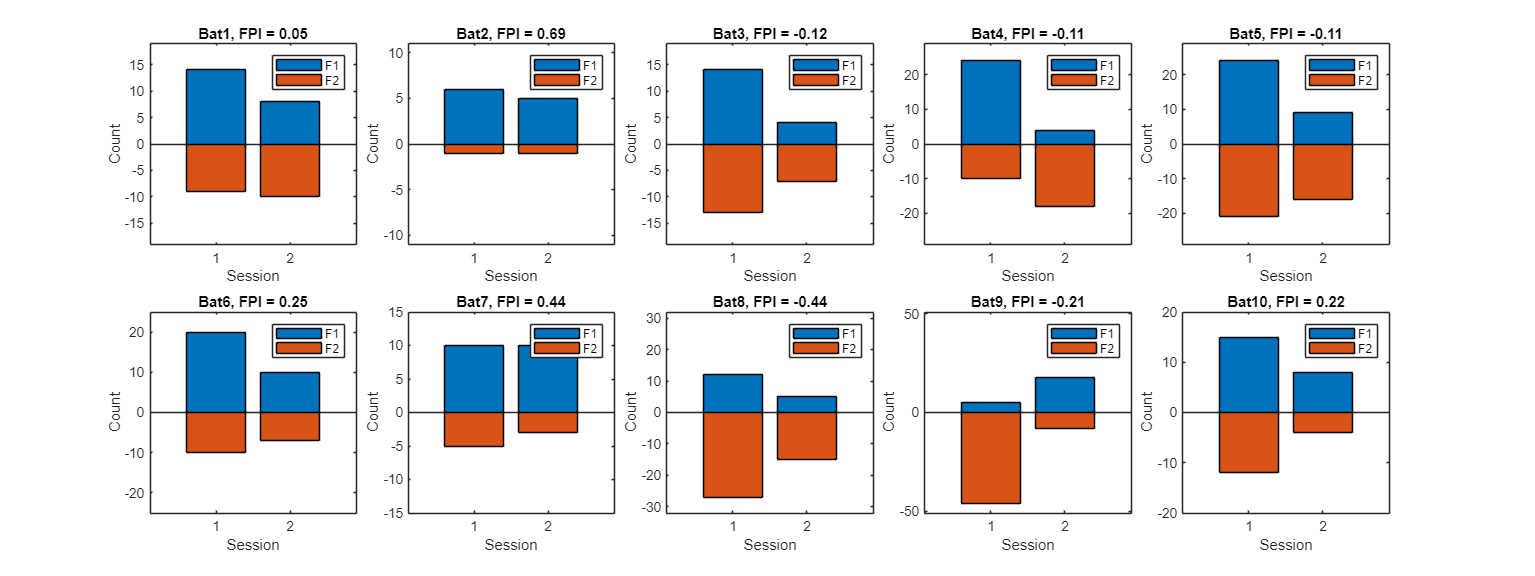

Unrecognized function or variable 'fig_dirpath'.

if opts.feeder_preference

% Load data
Landings_fd = extractLandings(BhvData,RewardData,mtData,'include','feeder'); % landings
n_session = mtData.n_session; % number of sessions
n_bats = length(mtData.bname); % number of bats
n_feeder = 2; % number of feeders

%%% FIGURE: feeder preference
fig = figure;
fontsize(fig, 24, "points")
set(fig, 'units','normalized','Position',[0.2 0.2 0.6 0.4]);
tiledlayout(2,5,"TileSpacing",'compact')
for bb = 1:n_bats   
    % Compute preference for feeder and/or reward. 
    % Feeder/reward preference index (PI), defined as (|F1-F2|/|F1+F2|) where F1 or F2 is the counts of landings on the feeder 1 or feeder 2.
    % The range is -1 < PI < 1. The larger PI means that the bat prefers to the feeder 1, while the lower PI means that the bat does the feeder 2.
    % PI = 0 means that there is no preference.

    % Feeder preference
    X = Landings_fd(bb).session_land;
    Y = Landings_fd(bb).closest_feeder(:,2);
    [feeder_pref, feeder_pref_index] = computePreferenceIndex(X,Y,n_session,n_feeder);

    feeder_pref(:,2) = feeder_pref(:,2)*-1;

    % reward_pref = zeros(n_session,2);
    % feeder_pref = zeros(n_session,2);
    % for ss = 1:n_session
    %     for ff = 1:2 % number of active feeder
    %         feeder_pref(ss,ff) = sum(Landings_fd(bb).session_land==ss & Landings_fd(bb).closest_feeder(:,2)==ff);
    %     end
    % 
    %     for flavor = 1:2 % number of flavor types
    %         reward_pref(ss,flavor) = sum(Landings_fd(bb).session_land == ss & Landings_fd(bb).reward == flavor);
    %     end
    % end
    % feeder_pref(:,2) = feeder_pref(:,2)*-1;
    % reward_pref(:,2) = reward_pref(:,2)*-1;
    
    % Feeder/reward preference index (PI), defined as (|F1-F2|/|F1+F2|) where F1 or F2 is the counts of landings on the feeder 1 or feeder 2.
    % The range is -1 < PI < 1. 
    % The larger PI means that the bat prefers to the feeder 1, while the
    % lower PI means that the bat does the feeder 2. PI = 0 means that
    % there is no preference
    % feeder_pref_index = -1*diff(abs(feeder_pref),1,2)./sum(abs(feeder_pref),2); 
    % reward_pref_index = -1*diff(abs(reward_pref),1,2)./sum(abs(reward_pref),2); 

    max_cnt = max(max(abs(feeder_pref)));

    % FIGURE
    nexttile
    bar(categorical(1:n_session),feeder_pref,'stacked')
    title(sprintf('Bat%s, FPI = %.2f',num2str(bb),mean(feeder_pref_index,'omitnan')))
    xlabel('Session')
    ylabel('Count')
    legend({"F1","F2"})
    ylim([-1*(max_cnt+5),max_cnt+5])
end
% Figure directory
FigDir = fullfile(figDir,'feeder_preference');
if isempty(dir(FigDir))
    mkdir(FigDir)
end
saveas(fig,fullfile(FigDir,'Feeder_preference_cdp.png'))

end

Reward preference

if opts.reward_preference

% Load data
Landings_fd = extractLandings(BhvData,RewardData,mtData,'include','feeder'); % landings
n_session = mtData.n_session; % number of sessions
n_bats = length(mtData.bname); % number of bats
n_reward = 2; % number of types of reward

%%% FIGURE: feeder preference
fig = figure;
fontsize(fig, 24, "points")
set(fig, 'units','normalized','Position',[0.2 0.2 0.6 0.4]);
tiledlayout(2,5,"TileSpacing",'compact')
for bb = 1:n_bats   
    % Compute preference for feeder and/or reward. 
    % Feeder/reward preference index (PI), defined as (|F1-F2|/|F1+F2|) where F1 or F2 is the counts of landings on the feeder 1 or feeder 2.
    % The range is -1 < PI < 1. The larger PI means that the bat prefers to the feeder 1, while the lower PI means that the bat does the feeder 2.
    % PI = 0 means that there is no preference.

    % Reward preference
    X = Landings_fd(bb).session_land;
    Y = Landings_fd(bb).reward;
    [reward_pref, reward_pref_index] = computePreferenceIndex(X,Y,n_session,n_reward);

    reward_pref(:,2) = reward_pref(:,2)*-1;

    max_cnt = max(max(abs(reward_pref)));

    % FIGURE
    nexttile
    bar(categorical(1:n_session),reward_pref,'stacked')
    title(sprintf('Bat%s, RPI = %.2f',num2str(bb),mean(reward_pref_index,'omitnan')))
    xlabel('Session')
    ylabel('Count')
    legend({"R1","R2"})
    ylim([-1*(max_cnt+5),max_cnt+5])
end
% Figure directory
FigDir = fullfile(figDir,'feeder_preference');
if isempty(dir(FigDir))
    mkdir(FigDir)
end
saveas(fig,fullfile(FigDir,'Reward_preference_cdp.jpg'))

end

#### Cumulative preference plot

Cumulative plot for the feeder preference

if opts.feeder_preference


Landings_fd = extractLandings(BhvData,RewardData,mtData,'include','feeder'); % landings
t_session = RewardData.t_session_sec; % time of the start of sessions in sec
t = BhvData.t; % timestamps for behavior data
n_session = mtData.n_session; % number of sessions
n_bats = length(mtData.bname); % number of bats

%%% FIGURE: cumulative plot of feeder landings
fig = figure;
fontsize(fig, 24, "points")
set(fig, 'units','normalized','Position',[0.2 0.2 0.6 0.4]);
tiledlayout(2,5,"TileSpacing",'compact')
fig_clr = {'b','r'};
for bb = 1:n_bats
    nexttile
    hold on
    for ff = 1:2 % number of active feeder
        
        t_rw_cum_sec = []; % time of reward delivery in sec
        reward_cum = []; % cumulative count of reward delivery
        
        for ss = 1:n_session
            t_rw_cum_sec = [t_rw_cum_sec; t_session(ss)];
            reward_cum = [reward_cum; 0];
            
            idx = Landings_fd(bb).closest_feeder(:,2)==ff & Landings_fd(bb).session_land == ss; % index for the current feeder
            t_rw_cum_sec = [t_rw_cum_sec; Landings_fd(bb).t_land_sec(idx)];
            reward_cum = [reward_cum;cumsum(ones(sum(idx),1))];
        end
        t_rw_cum_sec = [t_rw_cum_sec; t(end)];
        t_rw_cum_min = t_rw_cum_sec / 60; % convert to minutes
        reward_cum = [reward_cum; reward_cum(end)];
    
        stairs(t_rw_cum_min,reward_cum,'Color',fig_clr{ff})
    end
    title(sprintf('Bat%s',num2str(bb)))
    xlabel('Time (min)')
    ylabel('Count')
    
    % Draw the boundary of session
    y_lim = ylim;
    for ss = 2:n_session
        plot([t_session(ss)/60,t_session(ss)/60],[y_lim(1),y_lim(2)+1],'k')
    end

    for session = 1:n_session
        if mod(session,2) == 0
            if session ~= n_session
                xregion(t_session(session)/60,t_session(session+1)/60,'FaceColor',[80,190,225]/255)
            else
                xregion(t_session(session)/60,t(end)/60,'FaceColor',[80,190,225]/255)
            end
        else
            if session ~= n_session
                xregion(t_session(session)/60,t_session(session+1)/60,'FaceColor',[150,150,150]/255)
            else
                xregion(t_session(session)/60,t(end)/60,'FaceColor',[150,150,150]/255)
            end
        end
    end

    hold off

    f=get(gca,'Children');
    legend([f(length(f)),f(length(f)-1)],'F1','F2')
end

% Figure directory
FigDir = fullfile(figDir,'feeder_preference');
if isempty(dir(FigDir))
    mkdir(FigDir)
end
saveas(gcf,fullfile(FigDir,'Cumulative_feeder_preference_cdp.png'))

end

Cumulative plot for the reward preferences

if opts.reward_preference

Landings_fd = extractLandings(BhvData,RewardData,mtData,'include','feeder'); % landings
t_session = RewardData.t_session_sec; % time of the start of sessions in sec
t = BhvData.t; % timestamps for behavior data
n_session = mtData.n_session; % number of sessions
n_bats = length(mtData.bname); % number of bats

%%% FIGURE: cumulative plot of feeder landings
fig = figure;
fontsize(fig, 24, "points")
set(fig, 'units','normalized','Position',[0.2 0.2 0.6 0.4]);
tiledlayout(2,5,"TileSpacing",'compact')
fig_clr = {'b','r'};


for bb = 1:n_bats
    nexttile
    hold on
    for ff = 1:2 % number of flavor types
        
        t_rw_cum_sec = []; % time of reward delivery in sec
        reward_cum = []; % cumulative count of reward delivery
        
        for ss = 1:n_session
            t_rw_cum_sec = [t_rw_cum_sec; t_session(ss)];
            reward_cum = [reward_cum; 0];
            
            idx = Landings_fd(bb).reward==ff & Landings_fd(bb).session_land == ss; % index for the current reward
            t_rw_cum_sec = [t_rw_cum_sec; Landings_fd(bb).t_land_sec(idx)];
            reward_cum = [reward_cum;cumsum(ones(sum(idx),1))];
        end
        t_rw_cum_sec = [t_rw_cum_sec; t(end)];
        t_rw_cum_min = t_rw_cum_sec / 60; % convert to minutes
        reward_cum = [reward_cum; reward_cum(end)];
    
        stairs(t_rw_cum_min,reward_cum,'Color',fig_clr{ff})
    end
    title(sprintf('Bat%s',num2str(bb)))
    xlabel('Time (min)')
    ylabel('Count')
    
    % Draw the boundary of session
    y_lim = ylim;
    for ss = 2:n_session
        plot([t_session(ss)/60,t_session(ss)/60],[y_lim(1),y_lim(2)+1],'k')
    end

    for session = 1:n_session
        if mod(session,2) == 0
            if session ~= n_session
                xregion(t_session(session)/60,t_session(session+1)/60,'FaceColor',[80,190,225]/255)
            else
                xregion(t_session(session)/60,t(end)/60,'FaceColor',[80,190,225]/255)
            end
        else
            if session ~= n_session
                xregion(t_session(session)/60,t_session(session+1)/60,'FaceColor',[150,150,150]/255)
            else
                xregion(t_session(session)/60,t(end)/60,'FaceColor',[150,150,150]/255)
            end
        end
    end

    hold off

    f=get(gca,'Children');
    legend([f(length(f)),f(length(f)-1)],'R1','R2')
end

% Figure directory
FigDir = fullfile(figDir,'feeder_preference');
if isempty(dir(FigDir))
    mkdir(FigDir)
end
saveas(gcf,fullfile(FigDir,'Cumulative_reward_preference_cdp.jpg'))

end

## Ephys analysis

### Overview of single unit activity

Number of good units

n_goodUnits = spikeData.numGoodUnits; % number of good units
fprintf('Bat %s: %s on %s \n%d good units after manual curation.\n',bname_ephys,trjName,recDate,n_goodUnits)

Raster plot of example of spike traces

if opts.spike_raster


layers = Layers(strcmp({Layers.trjName},trjName) & strcmp({Layers.batid},bname_ephys)); % specify the layer
% Raster plot
figure
generateRasterPlotNP(spikeData,'layers',layers.layer,'t_window',[330,340]) % generate raster plot
title(sprintf('Bat %s: %s, %s',bname_ephys,trjName, recDate),'interpreter','none')

% save figure
saveDir = fullfile(figDir,'ephys'); % directory to save figure
if isempty(dir(saveDir)); mkdir(saveDir); end
saveas(gcf,fullfile(figDir,'ephys',sprintf('Rasterplot_bat%s_%s.jpg',bname_ephys,trjName)))

end

Waveform for all single units

if opts.SU_waveform

path_to_recording_dir = fullfile(ephysDir,bname_ephys,'Processed');
waveData = getSpikeWaveforms(path_to_recording_dir,probeNum,'kilosort_outdir_name',sprintf('kilosort_outdir_probe%d',probeNum));
saveDir = fullfile(rootdir,'analysis','figure','SU_waveform',bname_ephys,trjName);
if isempty(dir(saveDir)); mkdir(saveDir); end

for i = 1:length(waveData)
% for i = 1:1
    unit = waveData(i).unit; % unit id
    wv_window = waveData(i).window; % time range
    wv = waveData(i).wv; % waveform

    y_max = max(mean(wv,1)) * 2;
    y_min = min(mean(wv,1)) * 2;

    t = wv_window(1):1/30:wv_window(2);

    fig = figure('Visible','off'); hold on
    plot(t,wv,'Color',[150,150,150,10]/255)
    plot(t,mean(wv,1),'k','LineWidth',1)
    hold off
    title(sprintf('Unit %d',unit))
    xlabel('Time (ms)')
    ylabel('Amplitude (uv)')
    ylim([y_min, y_max])

    saveas(fig,fullfile(saveDir,sprintf("unit%d.png",unit)))
end

end

LFP correlation

if opts.lfp_corr


% LFP correlation
channel_depth = lfpData.channelPositions{probeNum}(:,2); % depth of channels
% The pearson correlation for the randomly sampled LFP traces between any channel pair is computed.
PlotLFPcorrelation(double(lfpData.lfp{probeNum}),channel_depth,'spsize',30000)

end

### Single unit activity during all flight

% % Bat for behavior
% bname = bname_ephys; % bat name
% batid = find(strcmp(mtData.bname,bname));
% 
% % Target behavior
% Landings = extractLandings(BhvData,RewardData,mtData,'include','all'); % all landings
% 
% % save directory
% saveDir = fullfile(rootdir,'analysis','figure','SU_raster',sprintf('Ephys%s',bname_ephys),trjName,'unclustered_flight',bname);
% if isempty(dir(saveDir)); mkdir(saveDir); end
% 
% % Target unit
% n_unit = spikeData.numGoodUnits;
% % unit = 1; % current unit
% for unit = 1:n_unit
%     % onset and end of target behavioral features
%     t_onset_sec = Landings(batid).t_flight_sec(:,1); % onsets of trials in sec
%     t_end_sec = Landings(batid).t_flight_sec(:,2); % ends of trials in sec
%     t_margin_sec = 2; % extract the spike times 5sec after and before trials in sec
% 
%     % features of the current unit
%     depth = spikeData.good_units.depth(unit); % depth of unit
%     unit_id = spikeData.good_units.cluster_id(unit); % unit id
%     sptimes_unit_sec = spikeData.good_units.spikeTimes_usec{unit}/1e6; % spike times of the current unit in sec
% 
%     layers = Layers(strcmp({Layers.trjName},trjName) & strcmp({Layers.batid},bname_ephys)); % specify the layer
%     region = 'unknown';
%     for i = 1:length(layers.layer)
%         if depth > layers.layer(i).depth(1) && depth < layers.layer(i).depth(2)
%             region = layers.layer(i).name; % brain region of the current unit
%         end
%     end
% 
%     %%% FIGURE: raster plot during the target behavior
%     fig = figure('Visible','off');
%     sortedRasterPlot(sptimes_unit_sec,t_onset_sec,t_end_sec,t_margin_sec)
%     title(sprintf('%s, #%s flight, #%s unit %d %s',recDate,bname,bname_ephys,unit_id,region),'Interpreter','none')
%     saveas(fig,fullfile(saveDir,sprintf('unit%d.jpg',unit)))
%     close(fig)
% end

### Single unit activity during all feeder/non-feeder flight

if opts.SU_raster_uncluster


% Bat for behavior
bname = bname_ephys; % bat name
batid = find(strcmp(mtData.bname,bname));

% Target behavior
% Landings = extractLandings(BhvData,RewardData,mtData,'include','all'); % landings
Landings = extractLandings(BhvData,RewardData,mtData,'include','all'); % feeder landings

% Target unit
n_unit = spikeData.numGoodUnits;
% unit = 1; % current unit
for unit = 1:n_unit
    % save directory
    saveDir = fullfile(rootdir,'analysis','figure','SU_raster',sprintf('Ephys%s',bname_ephys),trjName,'unclustered_flight',bname);
    if isempty(dir(saveDir)); mkdir(saveDir); end

    % features of the current unit
    depth = spikeData.good_units.depth(unit); % depth of unit
    unit_id = spikeData.good_units.cluster_id(unit); % unit id
    sptimes_unit_sec = spikeData.good_units.spikeTimes_usec{unit}/1e6; % spike times of the current unit in sec

    % unit region
    layers = Layers(strcmp({Layers.trjName},trjName) & strcmp({Layers.batid},bname_ephys)); % specify the layer
    region = 'unknown';
    for i = 1:length(layers.layer)
        if depth > layers.layer(i).depth(1) && depth < layers.layer(i).depth(2)
            region = layers.layer(i).name; % brain region of the current unit
        end
    end

    fig = figure('Visible','off');
    fontsize(fig, 20, "points")
    set(fig, 'units','normalized','Position',[0.2 0.2 0.65 0.35]);
    tl = tiledlayout(1,3,"TileSpacing",'compact');
    title(tl,sprintf('%s, #%s flight, #%s unit %d %s',recDate,bname,bname_ephys,unit_id,region),'Interpreter','none')
    for fd = 0:2 % current feeder
        if fd == 0
            idx_fd = ~Landings(batid).is_fd_land; % non feeder landings
        else
            idx_fd = Landings(batid).is_fd_land & Landings(batid).closest_feeder(:,2) == fd;
        end

        % onset and end of target behavioral features
        t_onset_sec = Landings(batid).t_flight_sec(idx_fd,1); % onsets of trials in sec
        t_end_sec = Landings(batid).t_flight_sec(idx_fd,2); % ends of trials in sec
        t_margin_sec = [-2 4]; % extract the spike times 5sec after and before trials in sec
        
        %%% FIGURE: raster plot during the target behavior
        nexttile
        sortedRasterPlot(sptimes_unit_sec,t_onset_sec,t_end_sec,t_margin_sec)
        title(sprintf('Feeder%d',fd))
        xlabel('t (s)')
        ylabel('flight')
    end
    saveas(fig,fullfile(saveDir,sprintf('unit%d.jpg',unit_id)))
    close(fig)
end

end

### Single unit activity: going to same feeder / vs differnt feeder

if opts.SU_raster_recurrent

% Bat for behavior
bname = bname_ephys; % bat name
batid = find(strcmp(mtData.bname,bname));

% Target behavior
% Landings = extractLandings(BhvData,RewardData,mtData,'include','all'); % landings
Landings = extractLandings(BhvData,RewardData,mtData,'include','feeder'); % feeder landings

fd_landed = Landings(batid).closest_feeder(:,2); % feeder landed
is_recurrent_land = fd_landed(1:end-1) == fd_landed(2:end); is_recurrent_land = [false; is_recurrent_land]; % if the bat returned to the same feeder

% save directory
saveDir = fullfile(rootdir,'analysis','figure','SU_raster',sprintf('Ephys%s',bname_ephys),trjName,'recurrent_flight',bname);
if isempty(dir(saveDir)); mkdir(saveDir); end

% Target unit
n_unit = spikeData.numGoodUnits;
% unit = 1; % current unit
for unit = 1:n_unit
    

    % features of the current unit
    depth = spikeData.good_units.depth(unit); % depth of unit
    unit_id = spikeData.good_units.cluster_id(unit); % unit id
    sptimes_unit_sec = spikeData.good_units.spikeTimes_usec{unit}/1e6; % spike times of the current unit in sec

    % unit region
    layers = Layers(strcmp({Layers.trjName},trjName) & strcmp({Layers.batid},bname_ephys)); % specify the layer
    region = 'unknown';
    for i = 1:length(layers.layer)
        if depth > layers.layer(i).depth(1) && depth < layers.layer(i).depth(2)
            region = layers.layer(i).name; % brain region of the current unit
        end
    end

    fig = figure('Visible','off');
    fontsize(fig, 20, "points")
    set(fig, 'units','normalized','Position',[0.2 0.2 0.4 0.35]);
    tl = tiledlayout(1,2,"TileSpacing",'compact');
    title(tl, sprintf('%s, #%s flight, #%s unit %d %s',recDate,bname,bname_ephys,unit_id,region),'Interpreter','none')
    for fd = 1:2 % current feeder
        if fd == 1
            idx_fd = is_recurrent_land; % recurrent landing
            fig_title = 'recurrent';
        else
            idx_fd = ~is_recurrent_land; % non recurrent landing
            fig_title = 'non-recurrent';
        end

        % onset and end of target behavioral features
        t_onset_sec = Landings(batid).t_flight_sec(idx_fd,1); % onsets of trials in sec
        t_end_sec = Landings(batid).t_flight_sec(idx_fd,2); % ends of trials in sec
        t_margin_sec = [-2 4]; % extract the spike times 5sec after and before trials in sec
        
        %%% FIGURE: raster plot during the target behavior
        nexttile
        sortedRasterPlot(sptimes_unit_sec,t_onset_sec,t_end_sec,t_margin_sec)
        title(fig_title)
        xlabel('t (s)')
        ylabel('flight')
    end
    saveas(fig,fullfile(saveDir,sprintf('unit%d.jpg',unit)))
    close(fig)
end

end

### Single unit activity during each cluster of flights

if opts.SU_raster_cluster


% Bat for behavior
bname = bname_ephys; % bat name
batid = find(strcmp(mtData.bname,bname));

% Target behavior
% Landings = extractLandings(BhvData,RewardData,mtData,'include','all'); % landings
Landings = extractLandings(BhvData,RewardData,mtData,'include','all');
TrjCluster = TrajClusteringHC(Landings,'cutoff',1.5,'depth',5,'distance','euclidean','linkage','ward','minpts',3,'n_smp',50,'n_dim',3); % Hierarchical clustering of trajectories
% TrjCluster = TrajClusteringDBSCAN(Landings,'minpts',3,'n_smp',100,'n_dim',3); % clustered trajectory by DBSCAN

cluster_list = unique(TrjCluster(batid).cluster); % list of cluster index

% Target unit
n_unit = spikeData.numGoodUnits;
% unit = 1; % current unit

for clu = 1:length(cluster_list)
    % save directory
    saveDir = fullfile(rootdir,'analysis','figure','SU_raster',sprintf('Ephys%s',bname_ephys),trjName,'clustered_flight',bname,sprintf('cluster%d',cluster_list(clu)));
    if isempty(dir(saveDir)); mkdir(saveDir); end

    idx = TrjCluster(batid).cluster == cluster_list(clu);
    % onset and end of target behavioral features
    t_onset_sec = Landings(batid).t_flight_sec(idx,1); % onsets of trials in sec
    t_end_sec = Landings(batid).t_flight_sec(idx,2); % ends of trials in sec
    t_margin_sec = [-2 2]; % extract the spike times 5sec after and before trials in sec
    
    for unit = 1:n_unit
        % features of the current unit
        depth = spikeData.good_units.depth(unit); % depth of unit
        unit_id = spikeData.good_units.cluster_id(unit); % unit id
        sptimes_unit_sec = spikeData.good_units.spikeTimes_usec{unit}/1e6; % spike times of the current unit in sec

        
        % info about the unit region
        layers = Layers(strcmp({Layers.trjName},trjName) & strcmp({Layers.batid},bname_ephys)); % specify the layer
        region = 'unknown';
        for i = 1:length(layers.layer)
            if depth > layers.layer(i).depth(1) && depth < layers.layer(i).depth(2)
                region = layers.layer(i).name; % brain region of the current unit
            end
        end
        
        %%% FIGURE: raster plot during the target behavior
        fig = figure('Visible','off');
        sortedRasterPlot(sptimes_unit_sec,t_onset_sec,t_end_sec,t_margin_sec)
        title(sprintf('%s, #%s flight, #%s unit %d %s',recDate,bname,bname_ephys,unit_id,region),'Interpreter','none')
        xlabel('t (s)')
        ylabel('flight')
        saveas(fig,fullfile(saveDir,sprintf('unit%d.jpg',unit_id)))
        close(fig)
    end
end

end

### Single unit activity during banana/pear flights

if opts.SU_raster_reward

% Bat for behavior
bname = bname_ephys; % bat name
batid = find(strcmp(mtData.bname,bname));

% Target behavior
% Landings = extractLandings(BhvData,RewardData,mtData,'include','all'); % landings
Landings = extractLandings(BhvData,RewardData,mtData,'include','feeder'); % feeder landings

% Target unit
n_unit = spikeData.numGoodUnits;
% unit = 1; % current unit
for unit = 1:n_unit
    % save directory
    saveDir = fullfile(rootdir,'analysis','figure','SU_raster',sprintf('Ephys%s',bname_ephys),trjName,'reward_flight',bname);
    if isempty(dir(saveDir)); mkdir(saveDir); end

    % features of the current unit
    depth = spikeData.good_units.depth(unit); % depth of unit
    unit_id = spikeData.good_units.cluster_id(unit); % unit id
    sptimes_unit_sec = spikeData.good_units.spikeTimes_usec{unit}/1e6; % spike times of the current unit in sec

    % unit region
    layers = Layers(strcmp({Layers.trjName},trjName) & strcmp({Layers.batid},bname_ephys)); % specify the layer
    region = 'unknown';
    for i = 1:length(layers.layer)
        if depth > layers.layer(i).depth(1) && depth < layers.layer(i).depth(2)
            region = layers.layer(i).name; % brain region of the current unit
        end
    end

    fig = figure('Visible','off');
    fontsize(fig, 20, "points")
    set(fig, 'units','normalized','Position',[0.2 0.2 0.65 0.35]);
    tl = tiledlayout(1,3,"TileSpacing",'compact');
    title(tl,sprintf('%s, #%s flight, #%s unit %d %s',recDate,bname,bname_ephys,unit_id,region),'Interpreter','none')
    for reward = 1:2 % banana = 1, pear = 2
        idx_fd = Landings(batid).reward == reward; % current reward
        

        % onset and end of target behavioral features
        t_onset_sec = Landings(batid).t_flight_sec(idx_fd,1); % onsets of trials in sec
        t_end_sec = Landings(batid).t_flight_sec(idx_fd,2); % ends of trials in sec
        t_margin_sec = [-2 10]; % extract the spike times 5sec after and before trials in sec
        
        %%% FIGURE: raster plot during the target behavior
        nexttile
        sortedRasterPlot(sptimes_unit_sec,t_onset_sec,t_end_sec,t_margin_sec)
        title(sprintf('Reward %d',reward))
        xlabel('t (s)')
        ylabel('flight')
    end
    saveas(fig,fullfile(saveDir,sprintf('unit%d.jpg',unit_id)))
    close(fig)
end

end

### Single unit activity during social/non-social flights

if opts.SU_raster_social

% Bat for behavior
bname = bname_ephys; % bat name
batid = find(strcmp(mtData.bname,bname));

% Target behavior
% Landings = extractLandings(BhvData,RewardData,mtData,'include','all'); % landings
Landings = extractLandings(BhvData,RewardData,mtData,'include','all'); % feeder landings

% Target unit
n_unit = spikeData.numGoodUnits;

n_bats = length(mtData.bname); % number of bats

% unit = 1; % current unit
for unit = 1:n_unit
    % save directory
    saveDir = fullfile(rootdir,'analysis','figure','SU_raster',sprintf('Ephys%s',bname_ephys),trjName,'social_flight',bname);
    if isempty(dir(saveDir)); mkdir(saveDir); end

    % features of the current unit
    depth = spikeData.good_units.depth(unit); % depth of unit
    unit_id = spikeData.good_units.cluster_id(unit); % unit id
    sptimes_unit_sec = spikeData.good_units.spikeTimes_usec{unit}/1e6; % spike times of the current unit in sec

    % unit region
    layers = Layers(strcmp({Layers.trjName},trjName) & strcmp({Layers.batid},bname_ephys)); % specify the layer
    region = 'unknown';
    for i = 1:length(layers.layer)
        if depth > layers.layer(i).depth(1) && depth < layers.layer(i).depth(2)
            region = layers.layer(i).name; % brain region of the current unit
        end
    end

    fig = figure('Visible','off');
    fontsize(fig, 20, "points")
    set(fig, 'units','normalized','Position',[0.05 0.05 0.9 0.8]);
    tl = tiledlayout(2,5,"TileSpacing",'compact');
    title(tl,sprintf('%s, #%s flight, #%s unit %d %s',recDate,bname,bname_ephys,unit_id,region),'Interpreter','none')
    for bb = 0:n_bats % banana = 1, pear = 2
        
        if bb == batid
            continue
        elseif bb == 0
            bname_target = 'empty place'; % no bat at the landing spot
            idx_fd = Landings(batid).closest_oth_dist >= 0.4;
        else
            bname_target = mtData.bname{bb}; % name of target bat
            idx_fd = Landings(batid).dist_oth(:,bb) < 0.4; % landing at the position close to the target bat
        end
        

        % onset and end of target behavioral features
        t_onset_sec = Landings(batid).t_flight_sec(idx_fd,1); % onsets of trials in sec
        t_end_sec = Landings(batid).t_flight_sec(idx_fd,2); % ends of trials in sec
        t_margin_sec = [-2 10]; % extract the spike times 5sec after and before trials in sec
        
        %%% FIGURE: raster plot during the target behavior
        nexttile
        sortedRasterPlot(sptimes_unit_sec,t_onset_sec,t_end_sec,t_margin_sec)
        title(sprintf('Toward bat %s',bname_target))
        xlabel('t (s)')
        ylabel('flight')
    end
    saveas(fig,fullfile(saveDir,sprintf('unit%d.jpg',unit_id)))
    close(fig)
end

end

#### Aligning the behavioral and neural data

% Load data
Landings = extractLandings(BhvData,RewardData,mtData,'include','all'); % landings
TrjCluster = TrajClusteringDBSCAN(Landings,'minpts',2,'n_smp',100,'n_dim',2); % clustered trajectory by DBSCAN

22 clusters for bat 1 are detected. 
11 clusters for bat 2 are detected. 
16 clusters for bat 3 are detected. 
35 clusters for bat 4 are detected. 
19 clusters for bat 5 are detected. 
11 clusters for bat 6 are detected. 
10 clusters for bat 7 are detected. 
9 clusters for bat 8 are detected. 
23 clusters for bat 9 are detected. 
12 clusters for bat 10 are detected. 


% ephysDir = fullfile(ephysDir,bname_ephys,'Processed');
% probeNum = 1; % probe number
% spikeData = loadSpikeData(ephysDir,'kilosort_out_folder_name', sprintf('kilosort_outdir_probe%d',probeNum)); % Load spike data
% Align spike and behavioral data
sp = extractSpikeDuringBehavior(spikeData,Landings,TrjCluster,mtData,'su');

#### Raster plot for each cluster of self flight

Spike activity during the flight of 14662 itself

bat_idx = 6; % a vector of bat index to be plotted
FigDir = fullfile(rootdir,'analysis','figure','RasterPlot_SU_flight');
RasterPlot_clusteredFlights(sp,bat_idx, FigDir)

#### Raster plot for flights for each feeders

bat_idx = 6; % a vector of bat index to be plotted
ephys_bat = '14662';
% bhv_types = {'flight','landing'}; % behavior types to plot
bhv_types = {'landing'}; % behavior types to plot

RasterPlot_unclusteredBehavior(sp,ephys_bat,bat_idx,bhv_types)

#### Raster plot during the landings before the flights to the feeders

bat_idx = 6; % a vector of bat index to be plotted
ephys_bat = '14662';
% bhv_types = {'flight','landing'}; % behavior types to plot
% bhv_types = {'landing'}; % behavior types to plot

RasterPlot_previousLandings(sp,ephys_bat,bat_idx)